u = 1; %force
b = 0.4 %damping constant

b = 0.4000

k = 0.4 %spring constant

k = 0.4000

m = 2 %mass

m = 2

dt = 0.1;
position  = 0;
velocity  = 0;
acceleration  = 0;

time = 0:dt:50;
y_values = zeros(1, length(time))

y_values =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


index = 1:1:length(time)

index =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


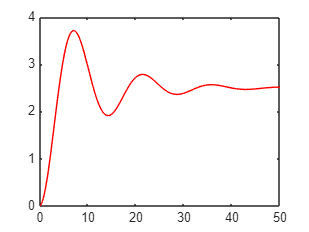


for num = index
    y_values(num) = position;

    acceleration = (u - (b*velocity) - (k*position))/m;
    velocity = velocity + acceleration * dt;
    position = position + velocity * dt;

    y_values(num) = position;

end

plot(time,y_values, "r")